# Running Kalman Filter for a Stationary Robot

Objective: This script will show you how  to implement the Kalman Filter for a Stationary Holonomic Robot. You will create a function (*KFStationary)* that runs the Kalman Filter prediction and update step specifically for a stationary robot. You will then use *test_KFStationary* to run the Kalman filter over a time series. 

Helper Functions used in this exercise:

- *plotKF: *This function will create a figure where you can step through the updates to mu and sigma over time. The center of the ellipse is the current guess and the 2 axes of the ellipse indicate the uncertainty in the x and y location

Execise:

In this exercise, we will run the Kalman Filter for robot that has a LIDAR sensor onboard but does not move. The robot will contiously be getting measurements fromt he LIDAR sensors (a simplified LIDAR with 4 angle range measurement readings pi/2 radians apart - similar to that tested in *simulate_LIDAR_sensor_noise*. Using these measurements, we will run the kalman filter to estimate the robot's pose. Because the robot is stationary - this simplifies the Kalman filter implementation because it minimizes the impact of the process noise. 

Complete the code below to 

- Initialize the robot and define sensor parameters

- Initialize Kalman filter. Define the inital mu, sigma,  and variance for each range measurement (4 for this simplified sensor) to define the Q matrix. You will also need to define the C Matrix to relate the measurements to the robot state. 

- Run the Kalman filter for N measurements. Store the value of of mu and sigma at each timestep so that it can be plotted later. 

**COMPLETE THE CODE BELOW** 

% 1. Initialization 

%Initial robot position
robotXY = [1.25;1;0]; %Insert code here
map = load('MAP102M1.txt');%TO DO: NEED TO LOAD THIS MAP FROM RELATIVE PATH (AA doesn't know how to do this)
maxRange = 4; 

%Simplify the LIDAR sensor and assume assume that it takes only 4 range measurements that are 90 degrees apart. 
alpha = [pi, pi/2, 0, -pi/2]; %insert code here

N = 20; %Number of measurements


%2. Kalman Filter Initialization
mu = [-.1; -.8];  %Insert Code Here
sigma = 2*eye(2);  %Insert Code Here
variance = [0.1 0.3 0.1, 0.3]; %THIS OPTIONAL LINE CAN BE ADDED BY STUDENT
Q = diag(variance); %Insert Code Here
C = zeros(length(alpha),2); % Insert Code Here
%OPTIONAL LINES TO DEFINE C%
for i = 1:length(alpha)
    C(i,:) = [-cos(alpha(i)) -sin(alpha(i))]; 
end

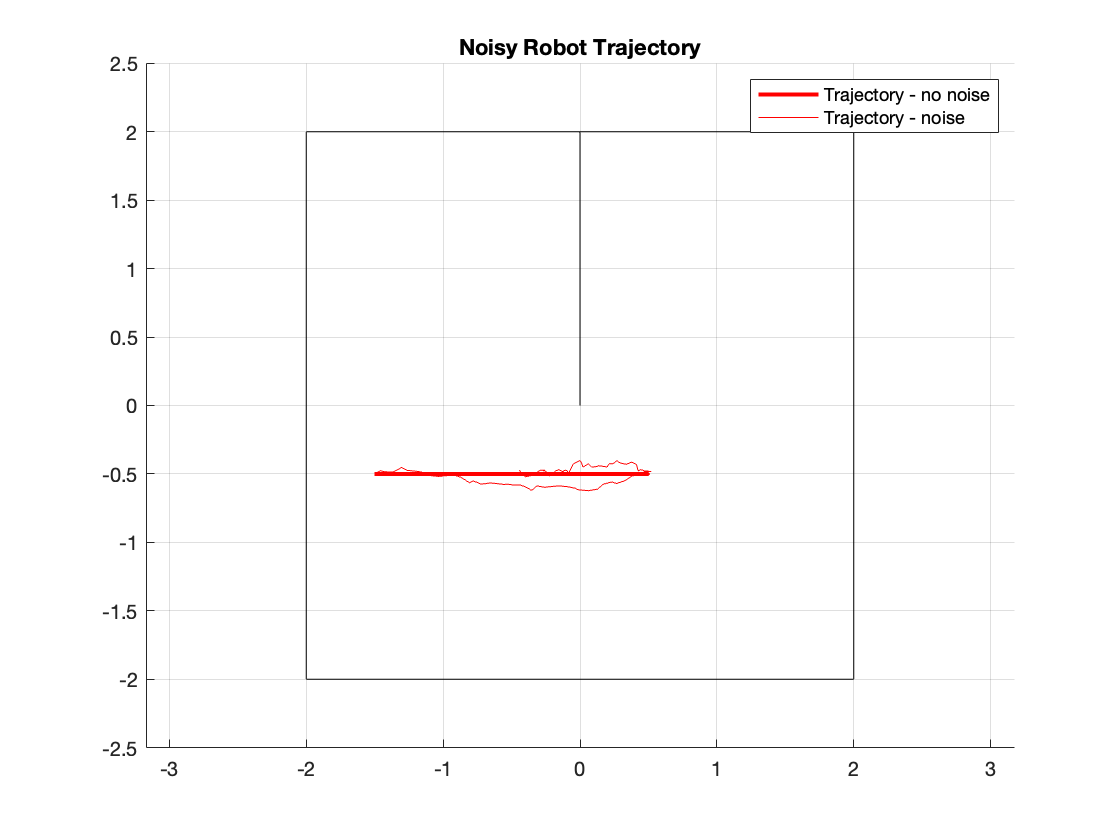

%4. Run Kalman Filter
%Create variables to store history of mu and sigma
mu_hist = zeros(2,N+1); %Insert Code Here
sigma_hist = zeros(2,2,N+1);%Insert Code Here
mu_hist(:,1) = mu;%Insert Code Here
sigma_hist(:,:,1) = sigma;%Insert Code Here

%Run Kalman filter for N measurements
%Insert Code Here
%STUDENT ADDS FOR LOOP BELOW
for i = 1:N
    [mu,sigma] = KFStationary(map, measurements(i,:)', mu, sigma, C, Q, alpha, maxRange);
    mu_hist(:,i+1) = mu;

    sigma_hist(:,:,i+1) = sigma;
end

Plot Kalman Filter Steps

plotKF(mu_hist, sigma_hist, robotXY, map); 
set(gcf,'Visible','on'); 

Check your Comprehension: Do your results make sense? How accurate is localized position?

To better understand the results:

1) Change the Kalman FIlter initialization parameters for mu, sigma, and Q. How does this alter the resulting localizated position? Given the covariance matrix Q, which axis of the ellipse should be longer? Is that true of the final ellipse (you may have to zoom in)? What happens to the ellipse from the initialized guess to the final estimate?